## part 1

% doc vision.CascadeObjectDetector
detector = vision.CascadeObjectDetector();

image_list = {'testowy_0_0000.jpeg','img/snapshot1.png', 'img/snapshot8.png', 'img/snapshot13.png'}

image_list = 1×4 cell array
    {'testowy_0_0000.jpeg'}    {'img/snapshot1.png'}    {'img/snapshot8.png'}    {'img/snapshot13.png'}



for i = 1:numel(image_list)
    RGB = imread(image_list{i});
    bboxes = detector(RGB);
    liczbaWykrytychTwarzy = size(bboxes,1)

liczbaWykrytychTwarzy = 1

liczbaWykrytychTwarzy = 1

liczbaWykrytychTwarzy = 1

liczbaWykrytychTwarzy = 1

## part 2

    % doc detectMinEigenFeatures
    GRAY=rgb2gray(RGB);
    corners = detectMinEigenFeatures(GRAY);
    corners
    figure; imshow(RGB)
    hold on; plot(corners.selectStrongest(250))


## part 3

corners =   2455×1 cornerPoints array with properties:

    Location: [2455×2 single]
      Metric: [2455×1 single]
       Count: 2455


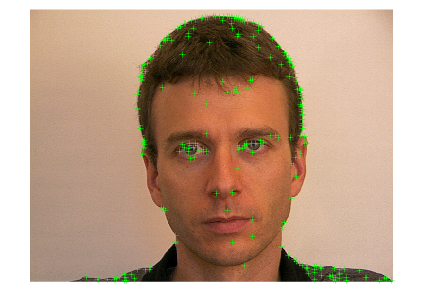

corners =   335×1 cornerPoints array with properties:

    Location: [335×2 single]
      Metric: [335×1 single]
       Count: 335


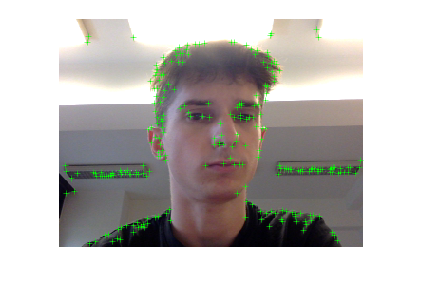

corners =   291×1 cornerPoints array with properties:

    Location: [291×2 single]
      Metric: [291×1 single]
       Count: 291


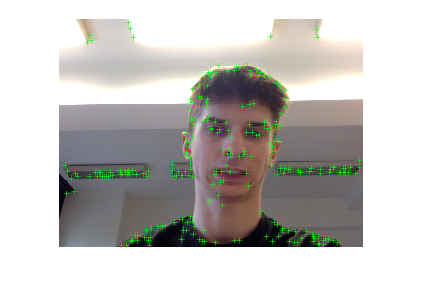

corners =   313×1 cornerPoints array with properties:

    Location: [313×2 single]
      Metric: [313×1 single]
       Count: 313


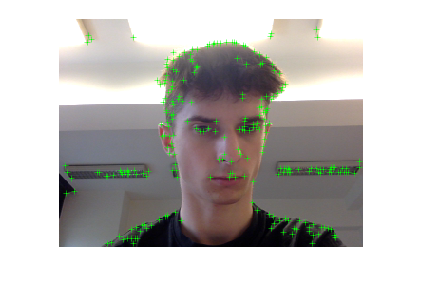

    % doc insertShape

    % doc insertMarker
    % doc bbox2points
    corners2 = detectMinEigenFeatures(GRAY, 'ROI', bboxes(1, :));
    
    xyPoints = corners2.Location;
    bboxPoints = bbox2points(bboxes(1, :));
    bboxPolygon = reshape(bboxPoints', 1, []);
    RGB2 = insertShape(RGB, 'Polygon', bboxPolygon, 'LineWidth', 3);
    RGB2 = insertMarker(RGB2, xyPoints, '+', 'Color', 'white');
    figure; imshow(RGB2)

wlasne przyklady

% RGB_1 = imread('img/snapshot1.png');
% RGB_2 = imread('img/snapshot7.png');
% RGB_3 = imread('img/snapshot17.png');
% 
% GRAY1 = rgb2gray(RGB_1);
% GRAY2 = rgb2gray(RGB_2);
% GRAY3 = rgb2gray(RGB_3);
% 
% bboxes1 = detector(RGB_1);
% bboxes2 = detector(RGB_2);
% bboxes3 = detector(RGB_3);
% 
% corners_1 = detectMinEigenFeatures(GRAY1, 'ROI', bboxes1(1, :));
% corners_2 = detectMinEigenFeatures(GRAY2, 'ROI', bboxes2(1, :));
% corners_3 = detectMinEigenFeatures(GRAY3, 'ROI', bboxes3(1, :));
% 
% xyPoints1 = corners_1.Location;
% xyPoints2 = corners_2.Location;
% xyPoints3 = corners_3.Location;
% 
% bboxPoints1 = bbox2points(bboxes1(1, :));
% bboxPoints2 = bbox2points(bboxes2(1, :));
% bboxPoints3 = bbox2points(bboxes3(1, :));
% 
% bboxPolygon1 = reshape(bboxPoints1', 1, []);
% bboxPolygon2 = reshape(bboxPoints2', 1, []);
% bboxPolygon3 = reshape(bboxPoints3', 1, []);
% 
% RGB_12 = insertShape(RGB_1, 'Polygon', bboxPolygon1, 'LineWidth', 3);
% RGB_12 = insertMarker(RGB_12, xyPoints1, '+', 'Color', 'white');
% figure; imshow(RGB_12)
% 
% RGB_22 = insertShape(RGB_2, 'Polygon', bboxPolygon2, 'LineWidth', 3);
% RGB_22 = insertMarker(RGB_22, xyPoints2, '+', 'Color', 'white');
% figure; imshow(RGB_22)
% 
% RGB_32 = insertShape(RGB_3, 'Polygon', bboxPolygon3, 'LineWidth', 3);
% RGB_32 = insertMarker(RGB_32, xyPoints3, '+', 'Color', 'white');
% figure; imshow(RGB_32)


## part 4

% doc insertObjectAnnotation
    noseDetector = vision.CascadeObjectDetector('Nose');
    mouthDetector = vision.CascadeObjectDetector('Mouth');
    
    noseBBox1=step(noseDetector, RGB);
    mouthBBox1=step(mouthDetector, RGB);
    
    RGB2 = RGB;
    RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox1,'nos');
    RGB2 = insertObjectAnnotation(RGB2, 'rectangle',mouthBBox1,'usta');
    imshow(RGB2)


## part 5

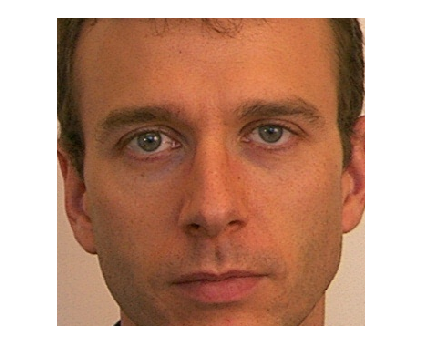

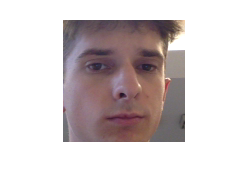

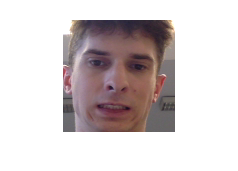

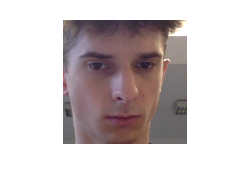

srodekTwarzy =   168.5000  168.5000


srodekNosa =   162.5000  273.5000
  167.5000  219.0000
  235.5000   95.5000
  122.0000  106.0000


poleTwarzy = 113569

poleNosa =         2009
        7600
       17017
       20856


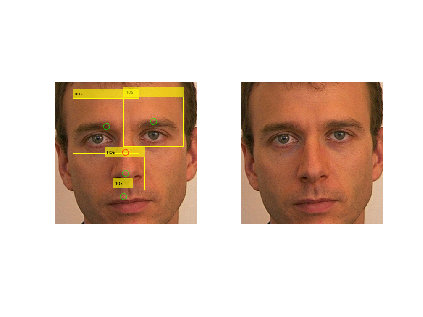

srodekTwarzy =    60.5000   60.5000



srodekNosa =

  0×2 empty double matrix



poleTwarzy = 14641


poleNosa =

  0×1 empty double column vector



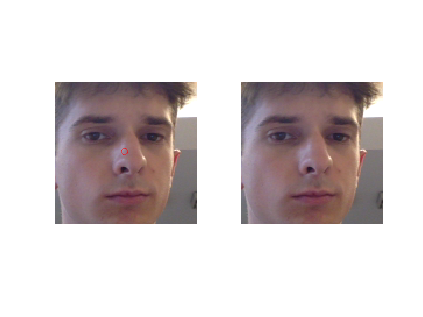

srodekTwarzy =    55.5000   55.5000


srodekNosa =    55.0000   66.5000


poleTwarzy = 12321

poleNosa = 1178

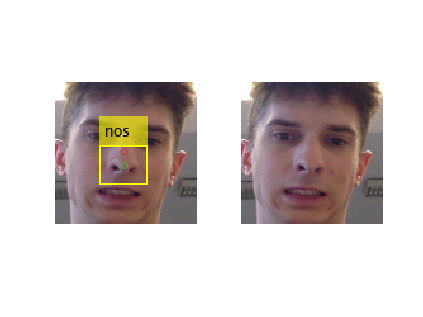

srodekTwarzy =    61.5000   61.5000


srodekNosa =    53.5000   75.5000


poleTwarzy = 15129

poleNosa = 357

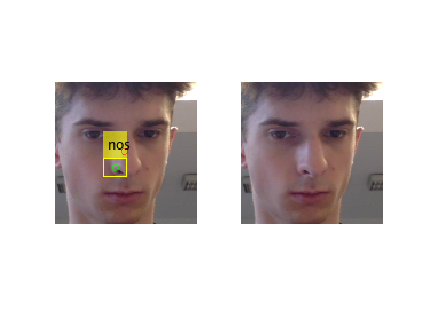

    faceIM = imcrop(RGB, bboxes(1, :)); % wycięcie obszaru twarzy 
    imshow(faceIM)
    
    % zawężenie detekcji cech tylko do obszaru twarzy
    noseBBox2=step(noseDetector, faceIM);
    mouthBBox2=step(mouthDetector, faceIM);
    
    % dodatkowe warunki weryfikujące cechy
    RGB2 = faceIM;
    RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox2,'nos');
    figure;subplot(1,2,1);imshow(RGB2)
     
    srodekTwarzy  = [bboxes(1,3)/2 bboxes(1,4)/2]
    % uwaga bboxes to wspolrzedne przed wycieciem twarzy
    srodekNosa = [noseBBox2(:,1)+noseBBox2(:,3)/2 noseBBox2(:,2)+noseBBox2(:,4)/2]
    hold on
    plot(srodekTwarzy(1),srodekTwarzy(2),'ro')
    plot(srodekNosa(:,1),srodekNosa(:,2),'go')
     
    proporcjaObszaruTwarzyiNosa = 0.3;
    poleTwarzy    = bboxes(1,3).*bboxes(1,4)
    poleNosa      = noseBBox2(:,3).*noseBBox2(:,4)
    nos_warunek_1 = poleNosa > proporcjaObszaruTwarzyiNosa*poleTwarzy;
    
    noseBBox2A = noseBBox2(nos_warunek_1,:);
    RGB2 = faceIM;
    RGB2 = insertObjectAnnotation(RGB2, 'rectangle',noseBBox2A,'nos');
    subplot(1,2,2);imshow(RGB2)

end